**Import Data**

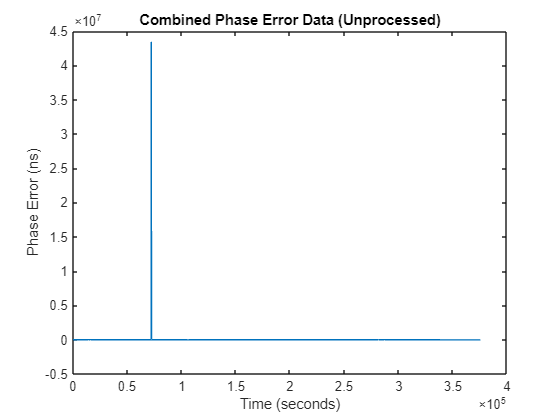

close all;
load("UnprocessedData_03-10-2025");
% data = [finalData(:,1), [finalData(1:63700,3);finalData(63701:end,4)]*-1, finalData(:,2)];
% save("UnprocessedData_03-10-2025","data");
data(:,2) = data(:,2)*-1;
plot(data(:,1),data(:,2));
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Combined Phase Error Data (Unprocessed)");

**Remove Data Glitches (Outliers)**

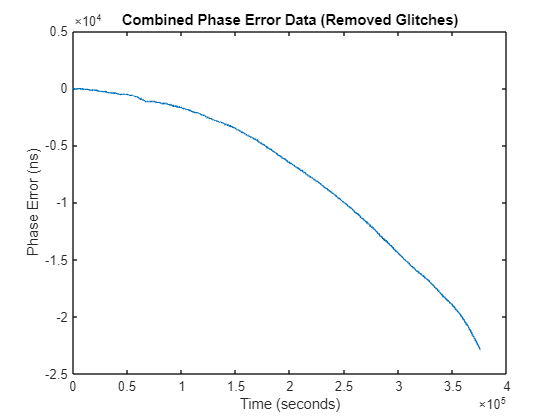

% Remove Outliers
phaseRange = 24000; %in nanoseconds
outliers = abs(data(:,2)) > phaseRange;
data(outliers,:) = [];
figure();
cla();
plot(data(:,1),data(:,2));
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Combined Phase Error Data (Removed Glitches)");

**Process data from the long-term lower-precision section of the test**

resolutionChangePoint = 69000;
longTermSection = data(resolutionChangePoint:10:end,:);
fit = polyfit(longTermSection(:,1),longTermSection(:,2),15);

phaseCurve = polyval(fit,longTermSection(:,1));

fitTemp = polyfit(longTermSection(:,1),longTermSection(:,3),15);

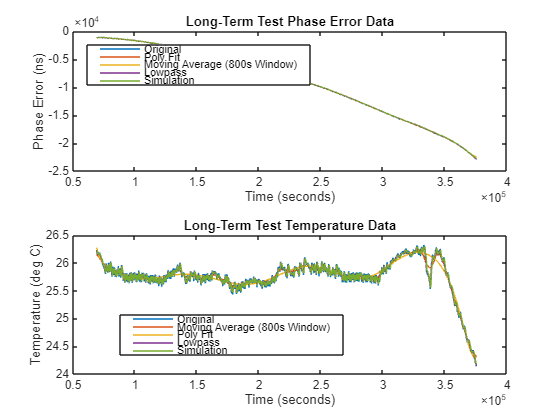

tempCurve = polyval(fitTemp,longTermSection(:,1));

phaseAvg = movmean(longTermSection(:,2),800);
tempAvg = movmean(longTermSection(:,3),800);

phaseLowpass = lowpass(longTermSection(:,2),1/1000,1/10,"ImpulseResponse","iir");
tempLowpass = lowpass(longTermSection(:,3),1/1000,1/10,"ImpulseResponse","iir");

simin = longTermSection;
run("DataProcessingSim.slx");
simTime = out.simout(round(longTermSection(1,1)/10)-9:size(longTermSection,1)+resolutionChangePoint/10,1);
phaseSim = out.simout(round(longTermSection(1,1)/10)-9:size(longTermSection,1)+resolutionChangePoint/10,2);
tempSim = out.simout(round(longTermSection(1,1)/10)-9:size(longTermSection,1)+resolutionChangePoint/10,3);

% movmean(longTermSection(:,2),10,)
figure();
cla();
tiledlayout(2,1);
nexttile;
plot(longTermSection(:,1), longTermSection(:,2));
hold on;
plot(longTermSection(:,1), phaseCurve);
plot(longTermSection(:,1), phaseAvg);
plot(longTermSection(:,1), phaseLowpass);
plot(longTermSection(:,1), phaseSim);
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Long-Term Test Phase Error Data");
legend(["Original" "Poly Fit" "Moving Average" "Lowpass" "Simulation"]);
nexttile;
plot(longTermSection(:,1), longTermSection(:,3));
hold on;
plot(longTermSection(:,1), tempAvg);
plot(longTermSection(:,1), tempCurve);
plot(longTermSection(:,1), tempLowpass);
plot(longTermSection(:,1), tempSim);
xlabel("Time (seconds)");
ylabel("Temperature (deg C)");
title("Long-Term Test Temperature Data");
legend(["Original" "Moving Average" "Poly Fit" "Lowpass" "Simulation"]);

nexttile(1)
legend(["Original", "Poly Fit", "Moving Average (800s Window)" "Lowpass" "Simulation"], "Position", [0.1556 0.7972 0.4000, 0.0976])

nexttile(2)
legend(["Original", "Moving Average (800s Window)", "Poly Fit" "Lowpass" "Simulation"], "Position", [0.2145 0.1543 0.4, 0.0976])

**The moving average processsing will be used. For temperature specifically, a lowpass filter should be applied for more accuracy (to simulate thermal capacitance of the CSAC)**

**Calculate frequency error from phase error**

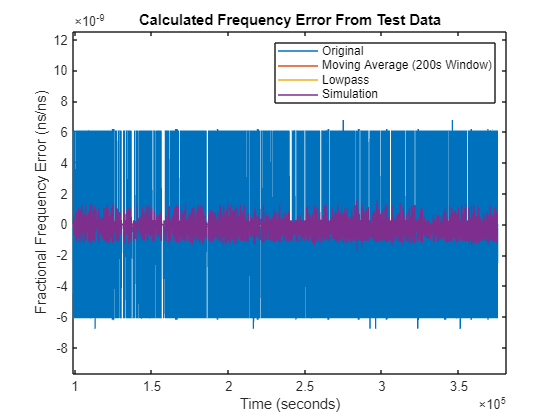

figure();
cla();
diffs = [diff(longTermSection(:,1)) diff(longTermSection(:,2))];
derivative = (diffs(:,2) ./ diffs(:,1)) * 10^-9; %ADJUSTED FOR UNITS OF ns/ns!!
derivative(isinf(derivative) | isnan(derivative)) = 0;
freqAvg = movmean(derivative,200);
freqLowpass = lowpass(derivative,1/1000,1/10,"ImpulseResponse","iir");

simin(1,2) = 0;
simin(2:end,2) = derivative;
run("DataProcessingSim.slx");
freqSim = out.simout(round(longTermSection(1,1)/10)-8:size(longTermSection,1)+resolutionChangePoint/10,2);

plot(longTermSection(2:end,1), derivative);
hold on;
plot(longTermSection(2:end,1), freqAvg);
plot(longTermSection(2:end,1), freqLowpass);
plot(longTermSection(2:end,1), freqSim);
xlabel("Time (seconds)");
ylabel("Fractional Frequency Error (ns/ns)");
title("Calculated Frequency Error From Test Data");
legend(["Original", "Moving Average (200s Window)" "Lowpass" "Simulation"]);

xlim([66935 378226]);
ylim([-0.0000000106 0.0000000139]);

%ylim([-3*10^-10 10^-10]);

**Display data to be exported**

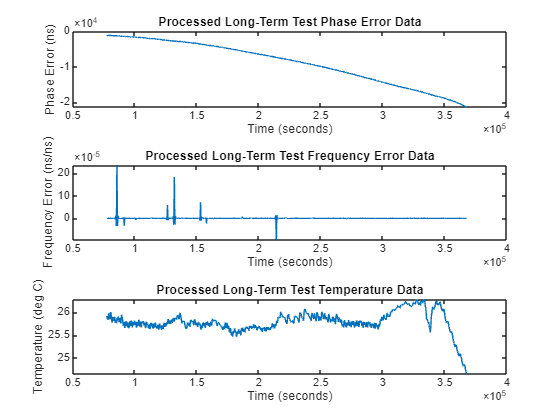

pad = 800;
compiledData = [longTermSection(pad+1:end-pad,1), phaseLowpass(pad+1:end-pad), freqLowpass(pad:end-pad), tempLowpass(pad+1:end-pad)];
figure();
cla();
tiledlayout(3,1);
nexttile;
plot(compiledData(:,1),compiledData(:,2));
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Processed Long-Term Test Phase Error Data");
nexttile;
plot(compiledData(:,1),compiledData(:,3));
xlabel("Time (seconds)");
ylabel("Frequency Error (ns/ns)");
title("Processed Long-Term Test Frequency Error Data");
nexttile;
plot(compiledData(:,1),compiledData(:,4));
xlabel("Time (seconds)");
ylabel("Temperature (deg C)");
title("Processed Long-Term Test Temperature Data");

writematrix(compiledData,"ProcessedData_105hrs.csv");

**Allan Deviation Plot**

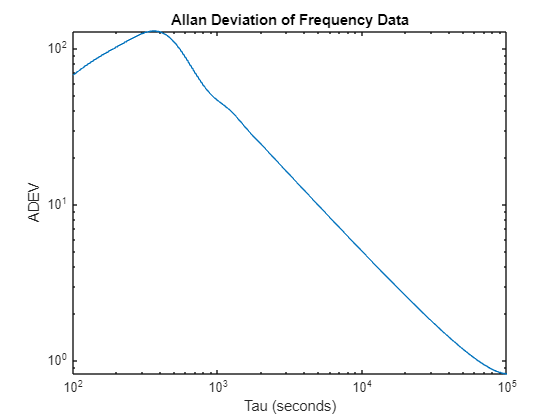

[AVAR, tau] = allanvar(freqLowpass,round(logspace(1,4,90)),0.1);
figure();
cla();
loglog(tau, sqrt(AVAR));
xlabel("Tau (seconds)");
ylabel("ADEV");
title("Allan Deviation of Frequency Data");

**Short-term, higher resolution section**

shortTermSection = data(1:resolutionChangePoint,:);

fit = polyfit(shortTermSection(:,1),shortTermSection(:,2),15);

phaseCurve = polyval(fit,shortTermSection(:,1));

fitTemp = polyfit(shortTermSection(:,1),shortTermSection(:,3),15);

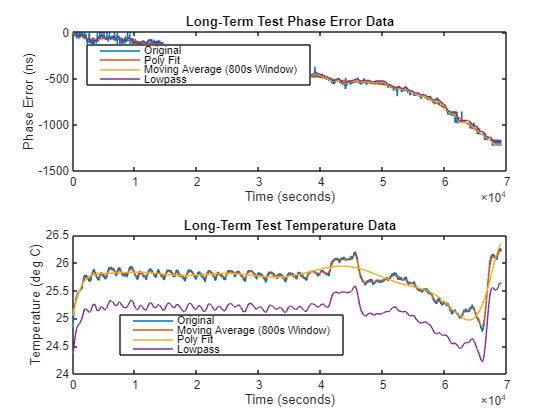

tempCurve = polyval(fitTemp,shortTermSection(:,1));

phaseAvg = movmean(shortTermSection(:,2),800);
tempAvg = movmean(shortTermSection(:,3),800);

phaseLowpass = lowpass(shortTermSection(:,2),1/1000,"ImpulseResponse","iir");
tempLowpass = lowpass(shortTermSection(:,3),1/1000,"ImpulseResponse","iir");

% movmean(longTermSection(:,2),10,)
figure();
cla();
tiledlayout(2,1);
nexttile;
plot(shortTermSection(:,1), shortTermSection(:,2));
hold on;
plot(shortTermSection(:,1), phaseCurve);
plot(shortTermSection(:,1), phaseAvg);
plot(shortTermSection(:,1), phaseLowpass);
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Long-Term Test Phase Error Data");
legend(["Original" "Poly Fit" "Moving Average" "Lowpass"]);
nexttile;
plot(shortTermSection(:,1), shortTermSection(:,3));
hold on;
plot(shortTermSection(:,1), tempAvg);
plot(shortTermSection(:,1), tempCurve);
plot(shortTermSection(:,1), tempLowpass);
xlabel("Time (seconds)");
ylabel("Temperature (deg C)");
title("Long-Term Test Temperature Data");
legend(["Original" "Moving Average" "Poly Fit" "Lowpass"]);

nexttile(1)
legend(["Original", "Poly Fit", "Moving Average (800s Window)" "Lowpass"], "Position", [0.1556 0.7972 0.4000, 0.0976])

nexttile(2)
legend(["Original", "Moving Average (800s Window)", "Poly Fit" "Lowpass"], "Position", [0.2145 0.1543 0.4, 0.0976])

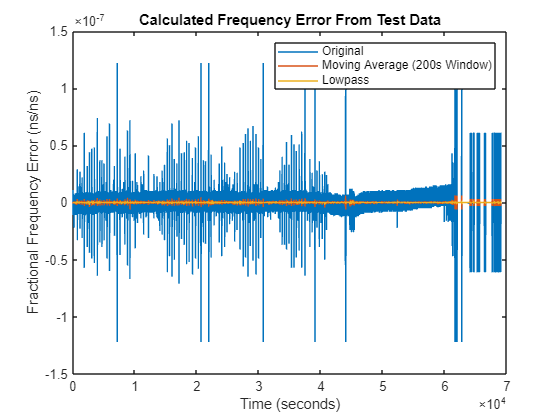


figure();
cla();
diffs = [diff(shortTermSection(:,1)) diff(shortTermSection(:,2))];
derivative = (diffs(:,2) ./ diffs(:,1)) * 10^-9; %ADJUSTED FOR UNITS OF ns/ns!!
derivative(isinf(derivative) | isnan(derivative)) = 0;
freqAvg = movmean(derivative,20);
freqLowpass = lowpass(derivative,1/100,1,"ImpulseResponse","iir");
plot(shortTermSection(2:end,1), derivative);
hold on;
plot(shortTermSection(2:end,1), freqAvg);
plot(shortTermSection(2:end,1), freqLowpass);
xlabel("Time (seconds)");
ylabel("Fractional Frequency Error (ns/ns)");
title("Calculated Frequency Error From Test Data");
legend(["Original", "Moving Average (200s Window)" "Lowpass"]);

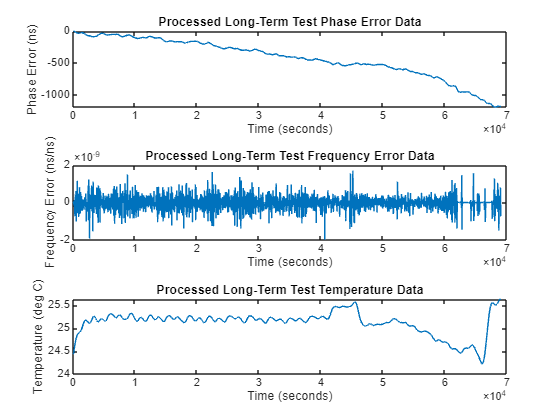


pad = 80;
compiledShortData = [shortTermSection(pad+1:end-pad,1), phaseLowpass(pad+1:end-pad), freqLowpass(pad:end-pad), tempLowpass(pad+1:end-pad)];
figure();
cla();
tiledlayout(3,1);
nexttile;
plot(compiledShortData(:,1),compiledShortData(:,2));
xlabel("Time (seconds)");
ylabel("Phase Error (ns)");
title("Processed Long-Term Test Phase Error Data");
nexttile;
plot(compiledShortData(:,1),compiledShortData(:,3));
xlabel("Time (seconds)");
ylabel("Frequency Error (ns/ns)");
title("Processed Long-Term Test Frequency Error Data");
nexttile;
plot(compiledShortData(:,1),compiledShortData(:,4));
xlabel("Time (seconds)");
ylabel("Temperature (deg C)");
title("Processed Long-Term Test Temperature Data");